% % 6-DoF linear and non-linear models
% syms X_theta_0 X_theta_1s X_delta_e Z_theta_0 Z_theta_1s Z_delta_e M_theta_0 M_theta_1s M_delta_e  % longitudinal stability derivatives
% syms Y_Delta_0_0 Y_theta_1c Y_delta_rud L_Delta_theta_0 L_theta_1c L_delta_rud N_Delta_theta_0 N_theta_1c N_delta_rud
% syms u v w L M N
% syms I_zz I_yy I_xx I_xz X Y Z real
% syms p q r 
% syms phi theta psi
% syms theta_0 theta_1s delta_e   % longitudinal inputs
% syms Delta(theta_0) theta_1c delta_r
% 
% 
% % Longitudinal state vector
% x_lon = [u; w; q; theta]
% 
% % Longitudinal inputs
% u_lon = [theta_0; theta_1s; delta_e]
% 
% % Lateral state vector
% x_lat = [v; p; r; phi; psi]
% 
% % Lateral inputs
% u_lat = [Delta(theta_0); theta_1c; delta_r]

% % Rotational matrices
% %R-ZYX Euler
% Rz = [cos(psi), -sin(psi), 0;
%     sin(psi), cos(psi), 0;
%     0, 0, 1]
% Ry = [cos(theta), 0, sin(theta);
%     0, 1, 0;
%     -sin(theta), 0, cos(theta)]
% Rx = [1, 0, 0;
%     0, cos(phi), -sin(phi);
%     0, sin(phi), cos(phi)]
% 
% % Rotation matrix from body frame to inertial frame
% % R_Euler = Rz*Ry*Rx

% 
% % Longitudinal input matrix
% B_lon = [X_theta_0 X_theta_1s X_delta_e;
%     Z_theta_0 Z_theta_1s Z_delta_e;
%     M_theta_0 M_theta_1s M_delta_e;
%     0 0 0]

% Lateral input matrix
% B_lat = [Y_Delta_0_0 Y_theta_1c Y_delta_rud;
%     L_Delta_theta_0 L_theta_1c L_delta_rud;
%     N_Delta_theta_0 N_theta_1c N_delta_rud;
%      0 0 0;
%      0 0 0]
% 
% % Nominal parameters
% g = 9.81;  % acceleration of free gravity in m/s^2.
% M_a = 3500;  % mass of helicopter in kg
% 
% 
% 
% % System parameters
% 
% % equations of motion
% u_dot = -(w*q - v*r) + (X/M_a) - g*sin(theta);
% v_dot = -(u*r - w*p) + (Y/M_a) - g*cos(theta)*sin(phi);
% w_dot = -(v*p - u*q) + (Z/M_a) - g*cos(theta)*cos(phi);
% % p_dot = ((I_yy - I_zz) * q * r + I_xz*(r_dot + p*q) + L)/I_xx;
% q_dot = ((I_zz - I_xx) * r * p + I_xz*(r^2 - p^2) + M)/I_yy;
% % r_dot = ((I_xx - I_yy) * p * q + I_xz*(p_dot - q*r) + N)/I_zz;
% phi_dot = p + q * sin(phi) * tan(theta) + r * cos(phi) * tan(theta);
% theta_dot = q * cos(phi) - r * sin(phi);
% psi_dot = q*sin(phi)*sec(theta) + r * cos(phi) * sec(theta);
% % 
% % x_dot = [u_dot; v_dot; w_dot; p_dot; q_dot; r_dot; phi_dot; theta_dot; psi_dot];
% x_lon_dot = [u_dot; w_dot; q_dot; theta_dot]
% 
% % u = [theta_0; theta_1s; delta_e; theta_4];
% y_lon_sym = [u; w; q; theta];
% 
% % Longitudinal state space
% A_sym = jacobian(x_lon_dot, x_lon)
% B_lon
% % B_sym = jacobian(x_lon_dot, u_lon)
% % C_sym = jacobian(y_sym, x_lon)
% % D_sym = jacobian(y_sym, u)
% 
% % linear_ss = ss(A_sym, B_sym, C_sym, D_sym)
% % Display equations of motion for inspection
% % fprintf("Equations of motion")
% for i = 1:9
%     disp(eval(['eq', num2str(i)]));
% end

% Hover:
% Position & height over and above the surface (respectively) remains constant
% Rotor RPM is constant
% Heading is constant

% Some estimates for the state and control matricies
% Only valid in hover
% Magnitudes may be off
clear
clc
close all

% Final function will look like this with inputs of forward flight speed,
% climb rate etc.
function [A,B,A_lon,B_lon,A_lat,B_lat] = Linearise(x,u)
% Inputs:  x - state vector [u v w p q r phi theta psi]'
%          u - controls vector [theta_0 Delta_theta theta_1c theta_1s delta_r delta_e]'
% Outputs: A - state matrix (9x9)
%          B - Controls matrix (9x6)
%          A_lon - longitudinal states matrix (4x4) [u w q theta]'
%          B_lon - longitudinal controls matrix (4x3) [theta_0 theta_1s delta_e]'
%          A_lat - lateral states matrix (5x5) [v p r phi psi]'
%          B_lat - lateral controls matrix (5x3) [Delta_theta theta_1c delta_r]'


Xu = -0.01;  % change in X-force given a change in u-velocity
Xw = 0.01;  % change in X-force given a change in vertical velocity
Xq = 3.608;  % change in X-force given a change in pitch rate
Zu = 0;  % change in vertical force given a change in u-velocity
Zw = -0.03;  % change in vertical force given a change in w-velocity
Zq = 0;  % change in vertical force given a change in pitch-rate
Mu = 0.01;  % change in pitching moment given a change in u-velocity
Mw = -0.005;  % change in pitching moment given a change in vertical velocity
Mq = -3.75;  % % change in pitching moment given a change in pitch rate
A_lon = [Xu Xw Xq -9.81;
         Zu Zw Zq 0    ;
         Mu Mw Mq 0    ;
         0  0  1  0    ];

Xtheta0 = 9.8;  % change in X-force given a change in average blade pitch
Xtheta1s = -31.1;  % change in X-force given a change in longitudinal cyclic pitch
Ztheta0 = -295.2;  % change in Z-force given a change in average blade pitch
Ztheta1s = 0;  % change in Z-force given a change in longitudinal cyclic pitch
Mtheta0 = 0;  % change in pitching moment given a change in average blade pitch
Mtheta1s = 11;  % change in pitching moment given a change in longitudinal cyclic pitch
B_lon = [Xtheta0 Xtheta1s 0;
         Ztheta0 Ztheta1s 0;
         Mtheta0 Mtheta1s 0;
         0       0        0];

Yv = -0.05;  % change in side force given a change in sideways velocity
Yp = -0.29;  % change in side force given a change in roll rate
Yr = 0;  % change in side force given a change in yaw rate
Lv = -0.01;  % change in rolling moment given a change in lateral velocity
Lp = -7.5;   % change in rolling moment given a change in roll rate
Lr = 0.1;  % change in rolling moment given a change in yaw rate  
Nv = -0.008;  % change in yawing moment given a change in lateral velocity
Np = -1.5;  % change in yawing moment given a change in roll rate
Nr = -0.25;  % change in yawing moment given a change in yaw rate
A_lat = [Yv Yp Yr 9.81 0;
         Lv Lp Lr 0    0;
         Nv Np Nr 0    0;
         0  1  0  0    0;
         0  0  1  0    0];

Ydeltatheta0 = 13.12;  % change in vertical force given a change in average blade pitch
Ytheta1c = -32.8;  % change in vertical force given a change in latitudinal blade pitch
Ldeltatheta0 = 5;  % change in rolling moment given a change in average blade pitch
Ltheta1c = 25;  % change in rolling moment given a change in latitudinal blade pitch
Ndeltatheta0 = -8;  % change in yawing moment given a change in average blade pitch
Ntheta1c = -10;  %  change in yawing moment given a change in latitudinal blade pitch
B_lat = [Ydeltatheta0 Ytheta1c 0;
         Ldeltatheta0 Ltheta1c 0;
         Ndeltatheta0 Ntheta1c 0;
         0            0        0;
         0            0        0];

% These will be filled in on the final version
A = zeros(9,9);
B = zeros(9,6);

end

[~,~,A_lon,B_lon,A_lat,B_lat] = Linearise

A_lon =   -0.010000000000000   0.010000000000000   3.608000000000000  -9.810000000000000
                   0  -0.030000000000000                   0                   0
   0.010000000000000  -0.005000000000000  -3.750000000000000                   0
                   0                   0   1.000000000000000                   0


B_lon = 1.0e+02 *

   0.098000000000000  -0.311000000000000                   0
  -2.952000000000000                   0                   0
                   0   0.110000000000000                   0
                   0                   0                   0


A_lat =   -0.050000000000000  -0.290000000000000                   0   9.810000000000000                   0
  -0.010000000000000  -7.500000000000000   0.100000000000000                   0                   0
  -0.008000000000000  -1.500000000000000  -0.250000000000000                   0                   0
                   0   1.000000000000000                   0                   0                   0
                   0                   0   1.000000000000000                   0                   0


B_lat =   13.119999999999999 -32.799999999999997                   0
   5.000000000000000  25.000000000000000                   0
  -8.000000000000000 -10.000000000000000                   0
                   0                   0                   0
                   0                   0                   0


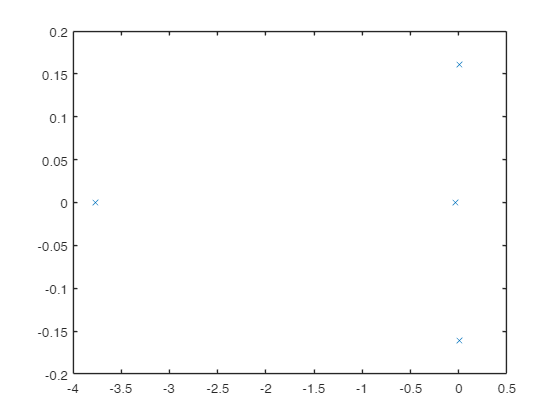


evalslon = eig(A_lon);
figure
plot(real(evalslon),imag(evalslon),'x');

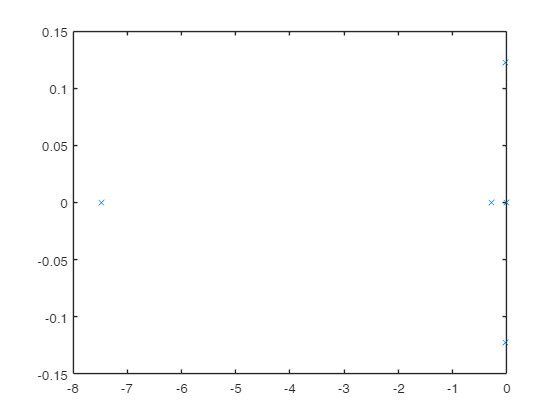


evalslat = eig(A_lat);
figure
plot(real(evalslat),imag(evalslat),'x')

% Latitudinal and longitudinal outputs
C_lon = [0 0 0 1];  % output theta
C_lat = [0 0 0 1 0;  % output phi & psi
         0 0 0 0 1];

% No feedforward components
D_lon = [0 0 0];
D_lat = [0 0 0;
         0 0 0;];


% Create longitudinal and latitudinal state spaces
heli_ss_lon = ss(A_lon, B_lon, C_lon, D_lon);
heli_ss_lat = ss(A_lat, B_lat, C_lat, D_lat)


heli_ss_lat =
 
  A = 
           x1      x2      x3      x4      x5
   x1   -0.05   -0.29       0    9.81       0
   x2   -0.01    -7.5     0.1       0       0
   x3  -0.008    -1.5   -0.25       0       0
   x4       0       1       0       0       0
   x5       0       0       1       0       0
 
  B = 
          u1     u2     u3
   x1  13.12  -32.8      0
   x2      5     25      0
   x3     -8    -10      0
   x4      0      0      0
   x5      0      0      0
 
  C = 
       x1  x2  x3  x4  x5
   y1   0   0   0   1   0
   y2   0   0   0   0   1
 
  D = 
       u1  u2  u3
   y1   0   0   0
   y2   0   0   0
 
Continuous-time state-space model.



% Assign state names
heli_ss_lon.StateName = {'u-vel'; 'w-vel'; 'pitch rate';
  'pitch angle'};
heli_ss_lat.StateName = {'v-vel'; 'roll rate'; 'yaw rate'; 'roll angle';
    'yaw angle'};

% Assign input variable names
heli_ss_lon.InputName = {'Average blade pitch'; 
                         'Longitudinal cyclic pitch';
                         'Elevator deflection'};
heli_ss_lat.InputName = {'Blade pitch difference';
                         'Latitudinal cyclic pitch';
                         'Rudder deflection'};

% Assign output variable names
heli_ss_lon.OutputName = {'theta'};
heli_ss_lat.OutputName = {'phi'; 'psi'};


% Create transfer functions
heli_tf_lon = tf(heli_ss_lon);
heli_tf_lat = tf(heli_ss_lat);

% Choose output mappings 
P_lon = heli_tf_lon(2)


P_lon =
 
  From input "Longitudinal cyclic pitch" to output "theta":
             11 s - 0.201
  -----------------------------------
  s^3 + 3.76 s^2 + 0.00142 s + 0.0981
 
Continuous-time transfer function.
Model Properties


P_lat = heli_tf_lat(2, 2)  % (Output X, input Y)


P_lat =
 
  From input "Latitudinal cyclic pitch" to output "psi":
        -10 s^3 - 112.7 s^2 - 4.062 s - 2.943
  -------------------------------------------------
  s^5 + 7.8 s^4 + 2.41 s^3 + 0.1984 s^2 + 0.03237 s
 
Continuous-time transfer function.
Model Properties


 
% Pre-compensator weighting
W1 = ss(0.1)


W1 =
 
  D = 
        u1
   y1  0.1
 
Static gain.
Model Properties



% Post-compensator weighting
K_lpf = 0.1;  % low pass filter gain
W_c2 = 0.1;  % low pass filter cutoff frequency
W2 = tf(K_lpf, [1/W_c2 1]);

% Design directions for closed-loop control (yet to be quantified)
% Attentuation for gusts assuming gust frequency is 1 <= freq_gust <= 10 (rad/sec)
% Gain margin of at least 6dB for each input-output mapping
% Phase margin of at least 45 degrees for each input-output mapping

% Longitudinal NCFSYN design
% Having seen some negative phase margins, we add a controller of the form
% K = 1 + as
[K_lon, ~, gamma_lon] = ncfsyn(P_lon, W1);
K_lon = -K_lon;
gamma_lon

gamma_lon =    1.604783497296040


long_marigns = allmargin(P_lon * K_lon)

long_marigns = struct with fields:
     GainMargin: [5.843735163392966 0.026682882264165 22.359408155113542]
    GMFrequency: [0 0.161379112311766 2.772594857002138]
    PhaseMargin: [-78.606246642063496 78.912497439644355]
    PMFrequency: [0.079103759009126 0.322897218896665]
    DelayMargin: [62.086145489928363 4.265391030618183]
    DMFrequency: [0.079103759009126 0.322897218896665]
         Stable: 1



% Latitudinal NCFSYN design
[K_lat, ~, gamma_lat] = ncfsyn(P_lat, W1);
K_lat = -K_lat;
gamma_lat

gamma_lat =    2.368003272961300


lat_margins = allmargin(P_lat * K_lat)

lat_margins = struct with fields:
     GainMargin: [0.025051054149002 0.116752402792209 53.675935455110064]
    GMFrequency: [0.127990024909243 0.155959931105504 11.485999317808533]
    PhaseMargin: 50.475195859397651
    PMFrequency: 1.117713364462890
    DelayMargin: 0.788179139970145
    DMFrequency: 1.117713364462890
         Stable: 1


### Longitudinal controller (ATTITUDE)

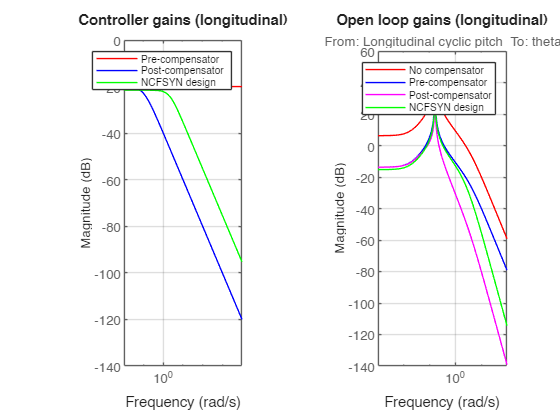

clf
subplot(1, 2, 1)
bodemag(W1, 'r', W2, 'b', K_lon, 'g', {1e-2, 1e4}); grid
legend("Pre-compensator", "Post-compensator", "NCFSYN design")
title("Controller gains (longitudinal)")

subplot(1, 2, 2)
bodemag(P_lon, 'r', P_lon*W1, 'b', W2*P_lon, 'm', P_lon*K_lon, 'g', {1e-3, 1e2}); grid
legend("No compensator", "Pre-compensator", "Post-compensator", "NCFSYN design")
title("Open loop gains (longitudinal)")

### Latitudinal controllers (ATTITUDE)

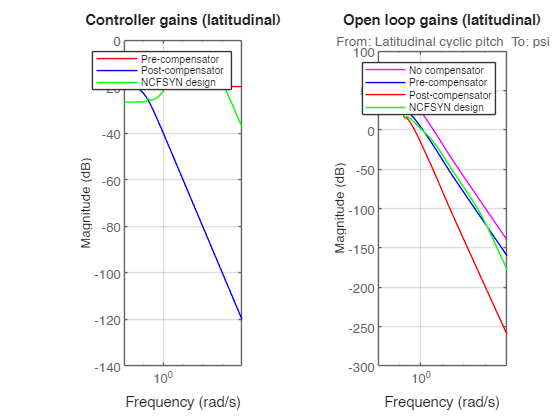

clf
subplot(1, 2, 1)
bodemag(W1, 'r', W2, 'b', K_lat, 'g', {1e-2, 1e4}); grid
legend("Pre-compensator", "Post-compensator", "NCFSYN design")
title("Controller gains (latitudinal)")

subplot(1, 2, 2)
bodemag(P_lat, 'm', P_lat*W1, 'b', W2*P_lat, 'r', P_lat*K_lat, 'g', {1e-2, 1e4}); grid
legend("No compensator", "Pre-compensator", "Post-compensator", "NCFSYN design")
title("Open loop gains (latitudinal)")

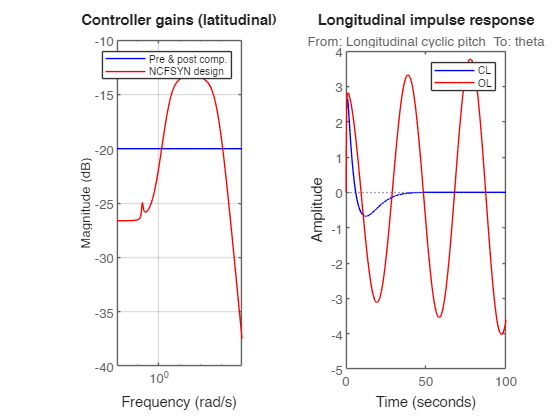

% Open loop response
impulse(feedback(P_lon, K_lon), 'b', P_lon, 'r', 100);
title("Longitudinal impulse response")
legend('CL', 'OL')

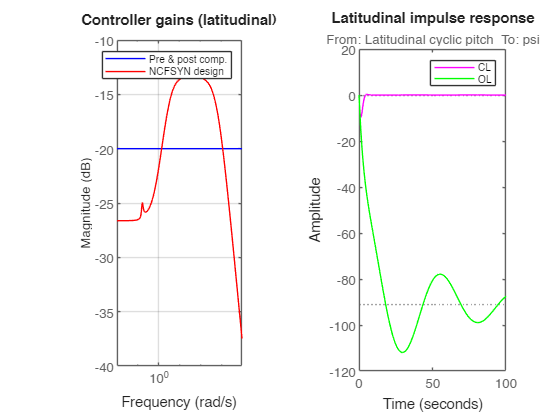


impulse(feedback(P_lat, K_lat), 'm', P_lat, 'g', 100);
title("Latitudinal impulse response")
legend('CL', 'OL')

size(K_lon)

State-space model with 1 outputs, 1 inputs, and 5 states.


size(K_lat)

State-space model with 1 outputs, 1 inputs, and 7 states.
